# Experiments plannification 

clear;
close all;
clc
addpath('./modules')

## Global variables definition

global nb_cath
global name_elements
global do_not_align
global optimize_price_box
global impose_alignments_name
global impose_alignments_index
global not_repeat
global repeat_only 
global repeat_at_least
global impose_plane_name
global impose_plane_index
global state
global f_plane_set
global nb_draw
global nb_draws_tot
global f_gradient_set
global path
global subfolder 
global mixture_name_list
global mixture_list

state="run";

## STOP button: to kill program whenever it is needed

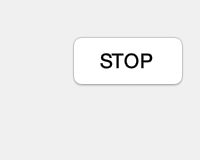

fig_stop_button=figure;
set(fig_stop_button, 'Position', get(fig_stop_button,'Position').*[1 1 0 0] + [-100 0 100 80]);
stop_button = uicontrol ( fig_stop_button , 'style' , ' pushbutton' , 'position', [35 35 60 30] , 'string' , 'STOP ', 'callback','state=kill_program') ;

## GUI for user to input the elements and number of cathodes 

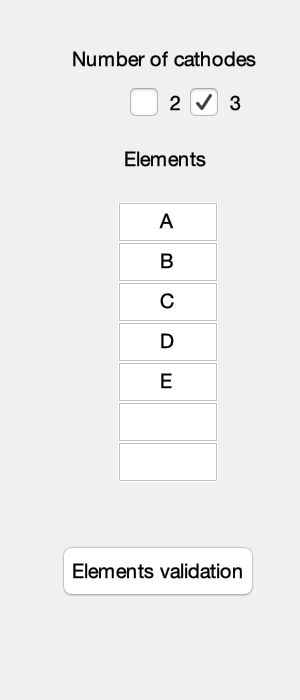

name_elements = 1×5 string array
    "A"    "B"    "C"    "D"    "E"


fig1 = figure ;
set(fig1, 'Position', get(fig1,'Position').*[1 1 0 0] + [0 -250 150 350]);

uicontrol ( fig1 , 'style' , ' text' , 'position', [35 300 100 30] , 'string' , 'Number of cathodes ' );
for nc=2:3
    nb_cathodes(nc-1) = uicontrol ( fig1 , 'style' , ' checkbox' , 'position', [3+30*nc,290,50,20] , 'Max' , 1 , 'string' , num2str(nc ));
end
uicontrol ( fig1 , 'style' , ' text' , 'position', [55 250 60 30] , 'string' , 'Elements ' );
for i=1:7
   elements(i) = uicontrol ( fig1 , 'style' , ' edit' , 'position', [60,250-i*20,50,20] , 'Max' , 1 , 'string' , '' );
end
valid_elements_button=uicontrol ( fig1 , 'style' , 'push' , 'position' , [30 50 100 30 ] ,'string' , 'Elements validation','callback','name_elements=get_elements(elements, fig1)');

uiwait(fig1);

## Get the elements and number of cathodes

If the user did not chose the number of cathode, error message is printed

nb_elements=size(name_elements,2);
nb_cath_box=get(nb_cathodes,'Value');
if nb_cath_box{1}==[1]
    nb_cath=2;
elseif nb_cath_box{2}==[1]
    nb_cath=3;
else 
    fig_5 = figure ;
    set( fig_5 ,  'position' , get(fig1,'Position').*[1 1 0 0] + [0 -50 400 75]);
    uicontrol ( fig_5 , 'style' , ' text' , 'position', [30 30 300 30] , 'FontSize', 16,'string' , 'No cathode !' );
    return
end

nb_type_mixture=nb_elements;

## Compute coordinates of the Simplexe Centroid Mixture points and generate the names of the mixtures.

[mixture,name_mixture] = coordinates_name_centroid_points(nb_elements,name_elements);


mixture_name_list=[]; 
for i=1:nb_elements
    mixture_name_list=[mixture_name_list;name_mixture{i}]; % list of all mixture name of simplexe centroid design
end

mixture_list=[]; 
for i=1:nb_elements
    mixture_list=[mixture_list;mixture{i}]; % list of all mixture points coordinates of simplexe centroid design
end

## Compute alignments / 1D gradients 

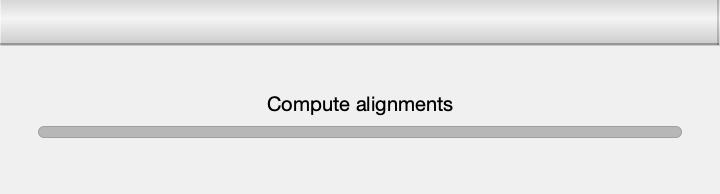

[alignments,name_alignement]=compute_alignments(mixture,name_mixture, nb_elements);

fig2 = figure ;
set( fig2 , 'position' , get(fig1,'Position').*[1 1 0 0] + [0 -250 350 700]);

## For 2 cathodes:

###  User selection conditions

if nb_cath==2
    uicontrol ( fig2 , 'style' , ' text' , 'position', [60 660 240 30] , 'string' , 'Optimize price and number of experiments' );
    optimize_price_box= uicontrol ( fig2 , 'style' , ' checkbox' , 'position', [40,675,15,15] ) ;
   
    for i=1:size(name_alignement)
        list_alignement(i)=[name_alignement(i,1)+"-"+name_alignement(i,2)+"-"+name_alignement(i,3)];
    end
    uicontrol ( fig2 , 'style' , ' text' , 'position', [50 630 100 30] , 'string' , 'Impose alignments: ' );
    list_align_impose=uicontrol ( fig2 , 'style' , 'listbox' , 'position', [50 540 200 100] , 'Max',size(name_alignement,1), 'string' , [' ',list_alignement]);
   
    uicontrol ( fig2 , 'style' , ' text' , 'position', [25 500 100 30] , 'string' , 'Not repeat: ' );
    not_repeat_list=uicontrol ( fig2 , 'style' , 'listbox' , 'position', [50 410 200 100] , 'Max',size(mixture_name_list,1), 'string' , [' ';mixture_name_list]) ;
    
    uicontrol ( fig2 , 'style' , ' text' , 'position', [35 370 100 30] , 'string' , 'Repeat only:  ' );
    repeat_only_list=uicontrol ( fig2 , 'style' , 'listbox' , 'position', [50 280 70 100] , 'Max',size(mixture_name_list,1), 'string' , [' ';mixture_name_list]);
    number_repet_only=[];
    fix_repetition_only_button=uicontrol ( fig2 , 'style' , 'push' , 'position' , [120 300 100 50 ] ,'string' , '<html>Maximum number <br>of repetitions >','callback','nb_repeat_only=fix_nb_repetition(repeat_only_list,fig2,[240 380 50 20 ])');
     
    uicontrol ( fig2 , 'style' , ' text' , 'position', [40 240 100 30] , 'string' , 'Repeat at least:  ' )
    repeat_at_least_list=uicontrol ( fig2 , 'style' , 'listbox' , 'position', [50 150 70 100] , 'Max',size(mixture_name_list,1), 'string' , [' ';mixture_name_list]);
    number_repeat_at_least=[];
    fix_repetition_at_least_button=uicontrol ( fig2 , 'style' , 'push' , 'position' , [120 175 100 50 ] ,'string' , '<html>Minimum number <br>of repetitions >','callback','nb_repeat_at_least=fix_nb_repetition(repeat_at_least_list,fig2,[240 260 50 20 ])');

    uicontrol ( fig2 , 'style' , ' text' , 'position', [30 90 200 30] , 'string' , 'Do not align mixture of order: ' );
    for da=1:nb_elements
        do_not_align_boxes(da)= uicontrol ( fig2 , 'style' , ' checkbox' , 'position', [50+da*30,75,50,20] , 'string' , num2str(da) );
    end
    valid_condition_button=uicontrol ( fig2 , 'style' , 'push' , 'position' , [100,40,50,20] ,'string' , 'Validation','callback','uiresume(fig2)');
    
    uiwait(fig2);


If user has ticked "Optimize price and number of experiments": GUI to input prices of all possible targets 

    if get(optimize_price_box,'Value')==1
        fig_price = figure ;
        nb_edit_per_line=0;
        div=10;
        % Compute number of boxes per lines to edit the window
        while nb_edit_per_line==0
            if mod((size(mixture_name_list,1)-1),div)==0
                nb_edit_per_line=div;
            else
                div=div-1;
            end
        end
        windows_height=(size(mixture_name_list,1)-1)/(nb_edit_per_line)*20+100;
        set( fig_price , 'position' , get(fig1,'Position').*[1 1 0 0] + [0 0  nb_edit_per_line*150 windows_height]);
        uicontrol ( fig_price , 'style' , ' text' , 'position', [20 windows_height-20 100 20] , 'string' , 'Target prices' );
        for i=0:(size(mixture_name_list,1)-1)/(nb_edit_per_line)-1
            for j=1:nb_edit_per_line
             uicontrol ( fig_price , 'style' , ' text' , 'position', [20+(j-1)*130 windows_height-50-20*i 100 30] , 'string' , mixture_name_list(i*nb_edit_per_line+j) );
             prices(i*nb_edit_per_line+j) = uicontrol ( fig_price , 'style' , ' edit' , 'position', [100+(j-1)*130,windows_height-40-i*20,50,20] , 'Max' , 1 , 'string' , '0' );
            end
        end
        
        uicontrol ( fig_price , 'style' , ' text' , 'position', [20 30 200 30] , 'string' , 'or load prices list in csv, path+name=' );
        path_prices=uicontrol ( fig_price , 'style' , ' edit' , 'position', [250 40 500 30] , 'string' , './  .csv' )  ;
        
        price_validation=uicontrol ( fig_price , 'style' , 'push' , 'position' , [120 10 50 20 ] ,'string' , 'OK','callback','uiresume(fig_price)');
        uiwait(fig_price);    
      

Store prices in a list.

        if get(path_prices,'string')~="./  .csv"
            table_prices=readtable(get(path_prices,'string'))
            prices_list=[string(table2array(table_prices(:,1))),string(table2array(table_prices(:,2)))] ; 
        else
            prices_list=[mixture_name_list(1:end-1),get(prices,'string')];
        end
    end
  

Get user selection conditions


    index_list_impose=get(list_align_impose,'Value');
    index_not_repeat=get(not_repeat_list,'Value');
    index_repeat_only=get(repeat_only_list,'Value');
    if sum(index_repeat_only)>1
        str_nb_repeat_only= get(nb_repeat_only,'string');
        if length(index_repeat_only)==1
            number_repet_only=str2num(str_nb_repeat_only);
        else
            for i=1:length(index_repeat_only)
                number_repet_only(i)=str2num(str_nb_repeat_only{i});
            end
        end
    end
 
    index_repeat_at_least=get(repeat_at_least_list,'Value');
    if sum(index_repeat_at_least)>1
        str_nb_repeat_at_least=get(nb_repeat_at_least,'string');
        if length(index_repeat_at_least)==1
            number_repeat_at_least=str2num(str_nb_repeat_at_least);
        else
            
            for i=1:length(index_repeat_at_least)
                number_repeat_at_least(i)=str2num(str_nb_repeat_at_least{i});
            end
        end
        
    end
    
    do_not_align_result=get(do_not_align_boxes,'Value');

Create lists constaining :

        - imposed alignments

    impose_alignments_name =[];
    impose_alignments_index=index_list_impose-1; % due to blank space left at the begining of the listbox
    for i=1:length(index_list_impose)
        if index_list_impose>1
            impose_alignments_name=[impose_alignments_name;name_alignement(index_list_impose(i)-1,:)];
        end
    end  

        - mixtures to not repeat i.e. mixtures by which the final set of gradients should pass once and only once.

    not_repeat=[];
    for i=1:length(index_not_repeat)
        if index_not_repeat(i)>1
            not_repeat=[not_repeat;mixture_name_list(index_not_repeat(i)-1)];
        end
    end

        - mixtures to repeat only N times [mixture_name,N]

    repeat_only=[];
    for i=1:length(index_repeat_only)
        if index_repeat_only(i)>1
            repeat_only=[repeat_only;mixture_name_list(index_repeat_only(i)-1),number_repet_only(i)];
        end
    end


        - mixtures that should be repeated at least N times [mixture_name,N]

    repeat_at_least=[];
    for i=1:length(index_repeat_at_least)
        if index_repeat_at_least(i)>1
            repeat_at_least=[repeat_at_least;mixture_name_list(index_repeat_at_least(i)-1),number_repeat_at_least(i)];
        end
    end


         - mixture to not align i.e. that should not appear more than once in the same gradient: if pure elements should not be aligned, then the list is ['A','B','C',...]


    do_not_align={};
    for i=1:length(do_not_align_result)
        if do_not_align_result{i}==1
            do_not_align{end+1}=(name_mixture{i})';
        end 
    end 


### Compute a first 1D gradients set 


    nb_draw=0;
    f_gradient_set=waitbar(0,"Compute gradient set: try number "+num2str(0));

    if get(optimize_price_box,'Value')==0
        nb_draws_tot=1;
    else
        nb_draws_tot=500;
    end
    
    [name_alignement_opt,alignement_opt] = gradients_set(name_mixture, mixture,alignments,name_alignement);
    list_target = listing_targets(name_alignement_opt);
    nb_alignments_best=size(name_alignement_opt,1)-1;


### If user has ticked "Optimize price and number of experiments": we draw nb_draws set of gradients to keep the one with the lowest price / lowest number of gradients

    if get(optimize_price_box,'Value')==1

Structures will store the set that minimizes the price among the nb_draw, and the set that minimizes the number of experiments among the nb_draw.

        exp_opt=struct;
        price_opt=struct;

Initialize with the first set built before

        price=price_calculation(prices_list,list_target(2:end));
   
        exp_opt.alignement_opt=alignement_opt;
        exp_opt.name_alignement_opt=name_alignement_opt;
        exp_opt.list_target=list_target;
        exp_opt.price=price;
        exp_opt.nb_alignments_best=nb_alignments_best;

        price_opt.alignement_opt=alignement_opt;
        price_opt.name_alignement_opt=name_alignement_opt;
        price_opt.list_target=list_target;
        price_opt.price=price;
        price_opt.nb_alignments_best=nb_alignments_best;

Make nb_draw sets of gradients to keep the best ones.

        for i=1:nb_draws_tot-1
           
            [name_alignement_opt_try,alignement_opt_try] = gradients_set(name_mixture, mixture,alignments,name_alignement);
            list_target_try = listing_targets(name_alignement_opt_try);
            price_try=price_calculation(prices_list,list_target_try(2:end));
            nb_alignments_try=size(name_alignement_opt_try,1)-1;
            if nb_alignments_try<exp_opt.nb_alignments_best
                 exp_opt.alignement_opt=alignement_opt_try;
                 exp_opt.name_alignement_opt=name_alignement_opt_try;
                 exp_opt.list_target=list_target_try;
                 exp_opt.price=price_try;
                 exp_opt.nb_alignments_best=nb_alignments_try;
            end
            if price_try<price_opt.price
                price_opt.alignement_opt=alignement_opt_try;
                price_opt.name_alignement_opt=name_alignement_opt_try;
                price_opt.list_target=list_target_try;
                price_opt.price=price_try;
                price_opt.nb_alignments_best=nb_alignments_try;
            end
             nb_draw=i;
        end


#### Representation of the set of gradients

        fig_representation_exp=plot_compo_space_gradients(nb_elements,mixture, name_mixture,name_elements, exp_opt.alignement_opt, 'b');
        title('Optimize number of experiments');
        fig_representation_price=plot_compo_space_gradients(nb_elements,mixture, name_mixture,name_elements, price_opt.alignement_opt, 'b');
        title('Optimize price');
        fig_5=figure;
        height_fig5= size(price_opt.list_target,1)*30;
        set( fig_5 , 'position' , [ 800 , 300 ,400 , height_fig5 ]);
        uicontrol ( fig_5 , 'style' , ' text' , 'position', [10 height_fig5-40 200  30] , 'string' , 'List of targets: optimize price' );
        uicontrol ( fig_5 , 'style' , ' text' , 'position', [200 height_fig5-40 200  30] , 'string' , 'List of targets: optimize experiments' );
        for i=1:size(price_opt.list_target,1)
            uicontrol ( fig_5 , 'style' , ' text' , 'position', [20 height_fig5-40-20*i 200  30] , 'string' , price_opt.list_target(i));
        end
        for i=1:size(exp_opt.list_target,1)
            uicontrol ( fig_5 , 'style' , ' text' , 'position', [200 height_fig5-40-20*i 200  30] , 'string' , exp_opt.list_target(i));
        end

### Else if user has not ticked "Optimize price and number of experiments": we keep the first set and plot the gradients

    else
        fig_representation=plot_compo_space_gradients(nb_elements,mixture, name_mixture,name_elements, alignement_opt, 'b');
        title('Set of experiments');
        fig5=figure;
        height_fig5= size(list_target,1)*20;
        set( fig5 , 'position' , [ 800 , 300 ,200 , height_fig5 ]);
        uicontrol ( fig5 , 'style' , ' text' , 'position', [10 height_fig5-40 200  30] , 'string' , 'List of targets' );
        for i=1:size(list_target,1)
            uicontrol ( fig5 , 'style' , ' text' , 'position', [20 height_fig5-40-20*i 200  30] , 'string' ,list_target(i));     
        end
         
    end
end

## For 3 cathodes :

###  User selection conditions

if nb_cath==3
    [name_plane,plane] =compute_planes(name_alignement,alignments,nb_type_mixture);
    

Get user selection conditions

    
    for i=1:size(name_plane)
        list_plane(i)=[name_plane(i,1)+"-"+name_plane(i,2)+"-"+name_plane(i,3)+"-"+name_plane(i,4)+"-"+name_plane(i,5)+"-"+name_plane(i,6)+"-"+name_plane(i,7)];
    end
   
    uicontrol ( fig2 , 'style' , ' text' , 'position', [60 660 240 30] , 'string' , 'Optimize price and number of experiments' );
    optimize_price_box= uicontrol ( fig2 , 'style' , ' checkbox' , 'position', [40,675,15,15] ) ;
    
    uicontrol ( fig2 , 'style' , ' text' , 'position', [50 630 100 30] , 'string' , 'Impose planes: ' );
    list_plane_impose=uicontrol ( fig2 , 'style' , 'listbox' , 'position', [50 540 200 100] , 'Max',size(name_plane,1), 'string' , [' ',list_plane]);
    
    
    uicontrol ( fig2 , 'style' , ' text' , 'position', [50 500 100 30] , 'string' , 'Not repeat: ' );
    not_repeat_list=uicontrol ( fig2 , 'style' , 'listbox' , 'position', [50 410 200 100] , 'Max',size(mixture_name_list,1), 'string' , [' ';mixture_name_list]); 
    
    
    uicontrol ( fig2 , 'style' , ' text' , 'position', [50 370 100 30] , 'string' , 'Repeat only:  ' );
    repeat_only_list=uicontrol ( fig2 , 'style' , 'listbox' , 'position', [50 280 70 100] , 'Max',size(mixture_name_list,1), 'string' , [' ';mixture_name_list]);
    number_repet_only=[];
    fix_repetition_only_button=uicontrol ( fig2 , 'style' , 'push' , 'position' , [120 300 100 50 ] ,'string' , '<html>Maximum number <br>of repetitions >','callback','nb_repet_only=fix_nb_repetition(repeat_only_list,fig2,[240 380 50 20 ])');
    
     uicontrol ( fig2 , 'style' , ' text' , 'position', [40 240 100 30] , 'string' , 'Repeat at least:  ' )
    repeat_at_least_list=uicontrol ( fig2 , 'style' , 'listbox' , 'position', [50 150 70 100] , 'Max',size(mixture_name_list,1), 'string' , [' ';mixture_name_list]);
    number_repeat_at_least=[];
    fix_repetition_at_least_button=uicontrol ( fig2 , 'style' , 'push' , 'position' , [120 175 100 50 ] ,'string' , '<html>Minimum number <br>of repetitions >','callback','nb_repet_at_least=fix_nb_repetition(repeat_at_least_list,fig2,[240 260 50 20 ])');

    
    valid_condition_button=uicontrol ( fig2 , 'style' , 'push' , 'position' , [150,100,50,20] ,'string' , 'Validation','callback','uiresume(fig2)');
    
    uiwait(fig2);
    

If user has ticked "Optimize price and number of experiments": GUI to input prices of all possible targets 

    if get(optimize_price_box,'Value')==1
        fig_price = figure ;
        nb_edit_per_line=0;
        div=10;
        while nb_edit_per_line==0
            if mod((size(mixture_name_list,1)-1),div)==0
                nb_edit_per_line=div;
            else
                div=div-1;
            end
        end
        windows_height=(size(mixture_name_list,1)-1)/(nb_edit_per_line)*20+100;
        set( fig_price , 'position' , get(fig1,'Position').*[1 1 0 0] + [0 0  nb_edit_per_line*150 windows_height]);
        uicontrol ( fig_price , 'style' , ' text' , 'position', [20 windows_height-20 100 20] , 'string' , 'Target prices' );
        for i=0:(size(mixture_name_list,1)-1)/(nb_edit_per_line)-1
            for j=1:nb_edit_per_line
             uicontrol ( fig_price , 'style' , ' text' , 'position', [20+(j-1)*130 windows_height-50-20*i 100 30] , 'string' , mixture_name_list(i*nb_edit_per_line+j) );
             prices(i*nb_edit_per_line+j) = uicontrol ( fig_price , 'style' , ' edit' , 'position', [100+(j-1)*130,windows_height-40-i*20,50,20] , 'Max' , 1 , 'string' , '0' );
            end
        end
        uicontrol ( fig_price , 'style' , ' text' , 'position', [20 30 200 30] , 'string' , 'or load prices list in csv, path+name=' );
        path_prices=uicontrol ( fig_price , 'style' , ' edit' , 'position', [250 40 500 30] , 'string' , './  .csv' )  ;
        
        pricevalidation=uicontrol ( fig_price , 'style' , 'push' , 'position' , [120 20 50 20 ] ,'string' , 'OK','callback','uiresume(fig_price)');
        uiwait(fig_price)

Store prices in a list.

        if get(path_prices,'string')~="./  .csv"
            table_prices=readtable(get(path_prices,'string'))
            prices_list=[string(table2array(table_prices(:,1))),string(table2array(table_prices(:,2)))] ; 
        else
            prices_list=[mixture_name_list(1:end-1),get(prices,'string')];
        end
    end 
   
    index_list_impose=get(list_plane_impose,'Value');
    index_not_repeat=get(not_repeat_list,'Value');
    index_repeat_only=get(repeat_only_list,'Value');
    if sum(index_repeat_only)>1
        str_nb_repeat_only= get(nb_repet_only,'string');
        if length(index_repeat_only)==1
            number_repet_only=str2num(str_nb_repeat_only);
        else
            
            for i=1:length(index_repeat_only)
                number_repet_only(i)=str2num(str_nb_repeat_only{i});
            end
        end
    end
 
    index_repeat_at_least=get(repeat_at_least_list,'Value');
    if sum(index_repeat_at_least)>1
        str_nb_repet_at_least=get(nb_repet_at_least,'string');
        if length(index_repeat_at_least)==1
            number_repeat_at_least=str2num(str_nb_repet_at_least);
        else
            for i=1:length(index_repeat_at_least)
                number_repeat_at_least(i)=str2num(str_nb_repet_at_least{i});
            end
        end
    end

Create lists constaining :

        - imposed planes

    
    impose_plane_name =[];
    impose_plane_index=index_list_impose-1;
    for i=1:length(index_list_impose)
        if index_list_impose>1
            impose_plane_name=[impose_plane_name;name_plane(index_list_impose(i)-1,:)];
        end
     end
    

        - mixtures to not repeat i.e. mixtures by which the final set of gradients should pass once and only once.

    
    not_repeat=[];
    for i=1:length(index_not_repeat)
        if index_not_repeat(i)>1
            not_repeat=[not_repeat;mixture_name_list(index_not_repeat(i)-1)];
        end
    end

        - mixtures to repeat only N times [mixture_name,N]

    repeat_only=[];
    for i=1:length(index_repeat_only)
        if index_repeat_only(i)>1
            repeat_only=[repeat_only;mixture_name_list(index_repeat_only(i)-1),number_repet_only(i)];
        end
    end

         - mixtures to repeat at least N times [mixture_name,N]

    
     repeat_at_least=[];
    for i=1:length(index_repeat_at_least)
        if index_repeat_at_least(i)>1
            repeat_at_least=[repeat_at_least;mixture_name_list(index_repeat_at_least(i)-1),number_repeat_at_least(i)];
        end
    end

NB: no condition such as "do_not_align" because the planes encompass 7 points and such conditions would lead to no solution 

### Compute a first 2D planes set 

    nb_draw=0;
    f_plane_set=waitbar(0,"Compute planes set: try number "+num2str(0));
    if get(optimize_price_box,'Value')==0
        nb_draws_tot=1;
    else
        nb_draws_tot=500;
    end
    [name_plane_opt,plane_opt] = planes_set(name_mixture, mixture,plane,name_plane);
    list_target = listing_targets_3cath(name_plane_opt);
     nb_planes_best=size(name_plane_opt,1)-1;

If user has ticked "Optimize price and number of experiments": we draw nb_draws set of planes to keep the one with the lowest price / lowest number of planes

    
    if get(optimize_price_box,'Value')==1
     

Structures will store the set that minimizes the price among the nb_draw, and the set that minimizes the number of experiments among the nb_draw.

        exp_opt=struct;
        price_opt=struct;
        price=price_calculation(prices_list,list_target(2:end));

Initialize with the first set built before

        exp_opt.plane_opt=plane_opt;
        exp_opt.name_plane_opt=name_plane_opt;
        exp_opt.list_target=list_target;
        exp_opt.price=price;
        exp_opt.nb_planes_best=nb_planes_best;

        price_opt.plane_opt=plane_opt;
        price_opt.name_plane_opt=name_plane_opt;
        price_opt.list_target=list_target;
        price_opt.price=price;
        price_opt.nb_planes_best=nb_planes_best;

Make nb_draw sets of planes to keep the best ones.

        for i=1: nb_draws_tot-1
           [name_plane_opt_try,plane_opt_try] = planes_set(name_mixture, mixture,plane,name_plane);
            list_target_try = listing_targets_3cath(name_plane_opt_try);
            price_try=price_calculation(prices_list,list_target_try(2:end));
            nb_planes_try=size(name_plane_opt_try,1)-1;
            if nb_planes_try<exp_opt.nb_planes_best
                 exp_opt.plane_opt=plane_opt_try;
                 exp_opt.name_plane_opt=name_plane_opt_try;
                 exp_opt.list_target=list_target_try;
                 exp_opt.price=price_try;
                 exp_opt.nb_planes_best=nb_planes_try;
            end
            if price_try<price_opt.price
                price_opt.plane_opt=plane_opt_try;
                price_opt.name_plane_opt=name_plane_opt_try;
                price_opt.list_target=list_target_try;
                price_opt.price=price_try;
                price_opt.nb_planes_best=nb_planes_try;
            end
            nb_draw=i;
        end
 

#### Representation of the set of planes

        fig_representation_exp=plot_compo_space_planes(nb_elements,mixture, name_mixture,name_elements,exp_opt.plane_opt, 'r' );
        title('Optimize number of experiments')
        fig_representation_price=plot_compo_space_planes(nb_elements,mixture, name_mixture,name_elements,price_opt.plane_opt, 'r');
        title('Optimize price');
        
        fig_5=figure;
        height_fig5= size(price_opt.list_target,1)*30;
        set( fig_5 , 'position' , [ 800 , 300 ,400 , height_fig5 ]);
        uicontrol ( fig_5 , 'style' , ' text' , 'position', [10 height_fig5-40 200  30] , 'string' , 'List of targets: optimize price'  );
        uicontrol ( fig_5 , 'style' , ' text' , 'position', [200 height_fig5-40 200  30] , 'string' , 'List of targets: optimize experiments' );
        
        for i=1:size(price_opt.list_target,1)
            uicontrol ( fig_5 , 'style' , ' text' , 'position', [20 height_fig5-40-20*i 200  30] , 'string' , price_opt.list_target(i));
        end
        for i=1:size(exp_opt.list_target,1)
            uicontrol ( fig_5 , 'style' , ' text' , 'position', [200 height_fig5-40-20*i 200  30] , 'string' , exp_opt.list_target(i));
        end
   

### Else if user has not ticked "Optimize price and number of experiments": we keep the first set and plot the planes 

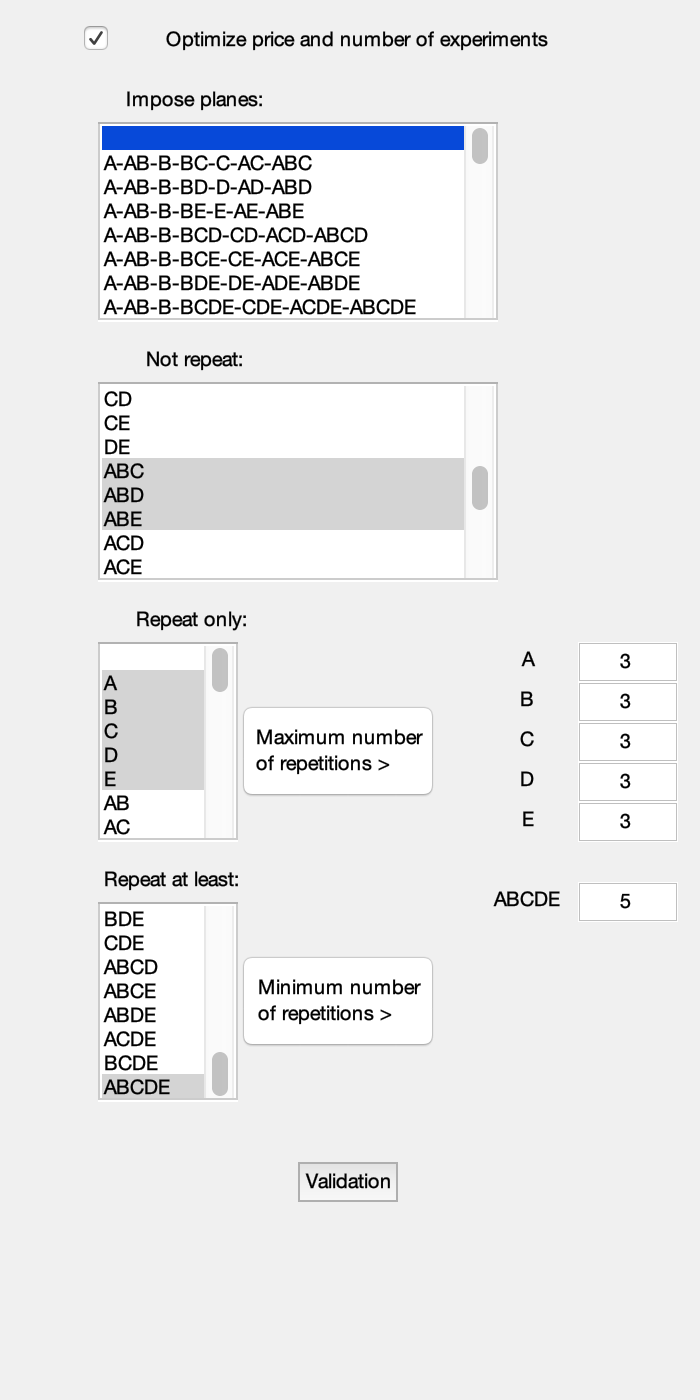

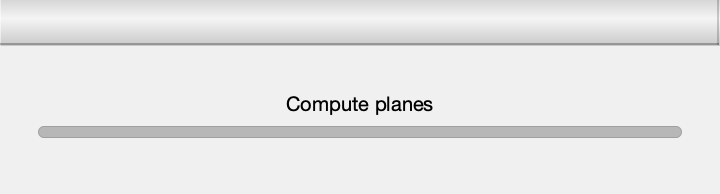

nb_repet_only =   1×5 UIControl array:

    UIControl    UIControl    UIControl    UIControl    UIControl


nb_repet_at_least =   UIControl with properties:

              Style: 'edit'
             String: ''
    BackgroundColor: [0.9400 0.9400 0.9400]
           Callback: ''
              Value: 0
           Position: [290 240 50 20]
              Units: 'pixels'

  Show all properties


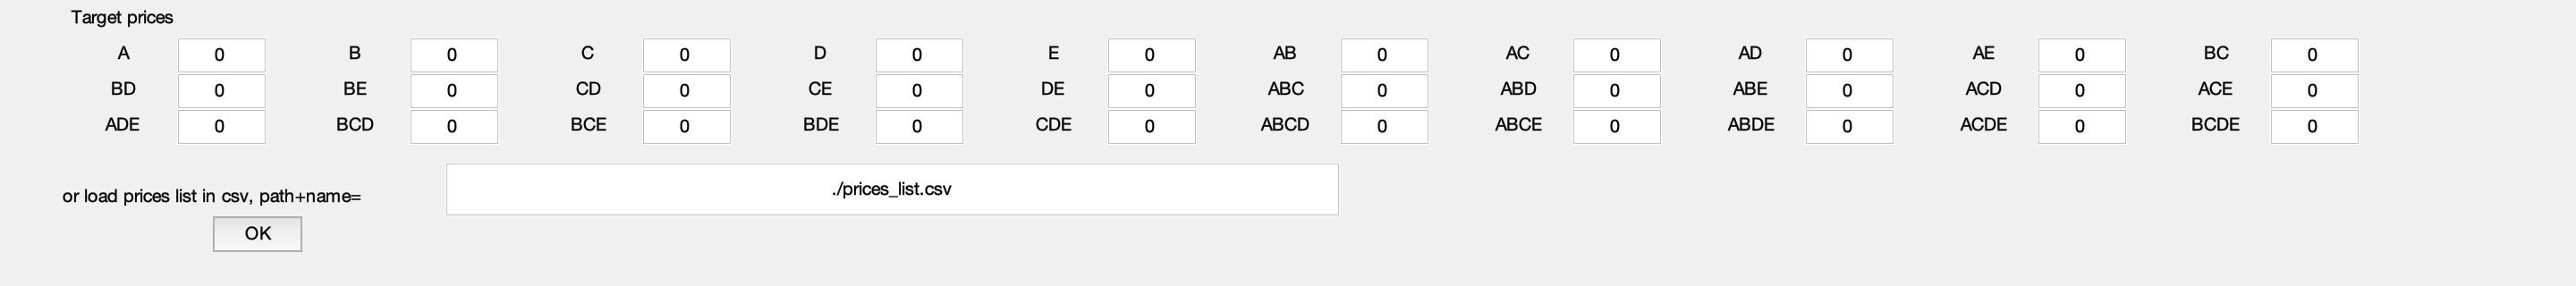

table_prices = 30×2 table
     Var1      Var2
    _______    ____

    {'A'  }    100 
    {'B'  }     90 
    {'C'  }    100 
    {'D'  }    130 
    {'E'  }     80 
    {'AB' }    190 
    {'AC' }    200 
    {'AD' }    230 
    {'AE' }    180 
    {'BC' }    190 
    {'BD' }    220 
    {'BE' }    170 
    {'CD' }    230 
    {'DE' }    210 
    {'CE' }    180 
    {'ABC'}    290 


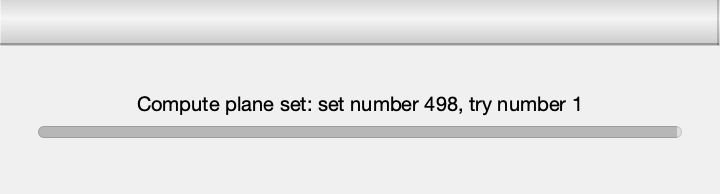

ans = 4

ans = 4

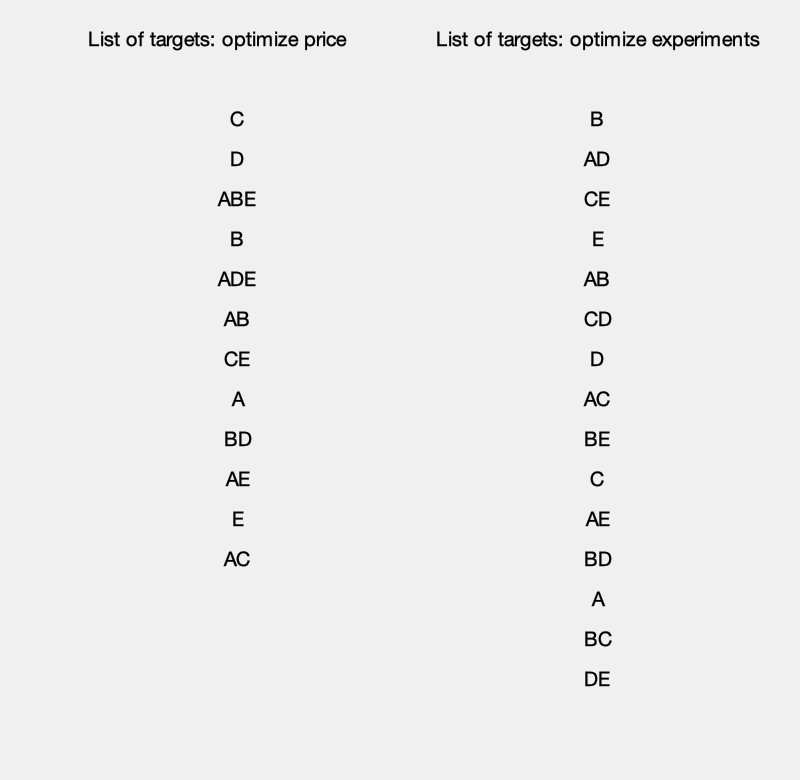

    else
        fig_representation=plot_compo_space_planes(nb_elements,mixture, name_mixture,name_elements,plane_opt, 'r',3 );
        title('Set of planes');
     
        
        fig5=figure;
        height_fig5= size(list_target,1)*20;
        set( fig5 , 'position' , [ 800 , 300 ,200 , height_fig5 ]);
        uicontrol ( fig5 , 'style' , ' text' , 'position', [10 height_fig5-40 200  30] , 'string' , 'List of targets'  );
 
        for i=1:size(list_target,1)
            uicontrol ( fig5 , 'style' , ' text' , 'position', [20 height_fig5-40-20*i 200  30] , 'string' ,list_target(i));
        end
       
    end
    
    
end

## Save the set of gradients/planes and user condition for the draw

### GUI for input the path for save

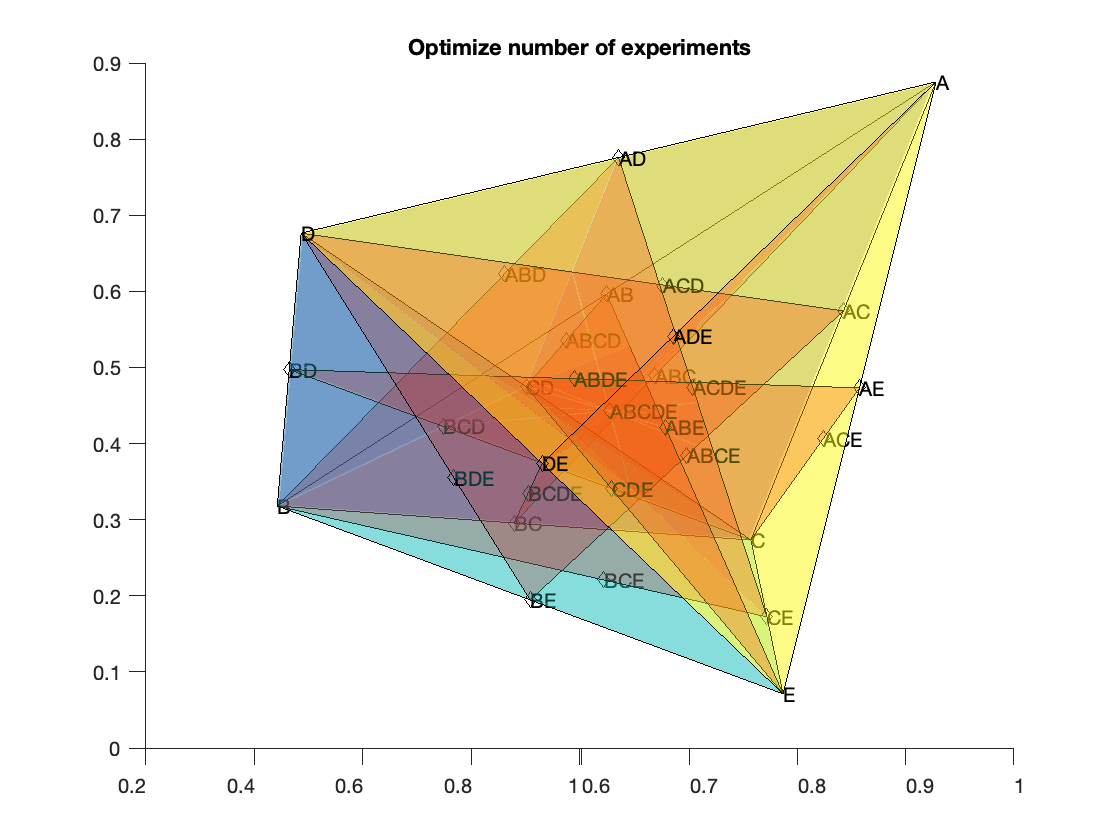

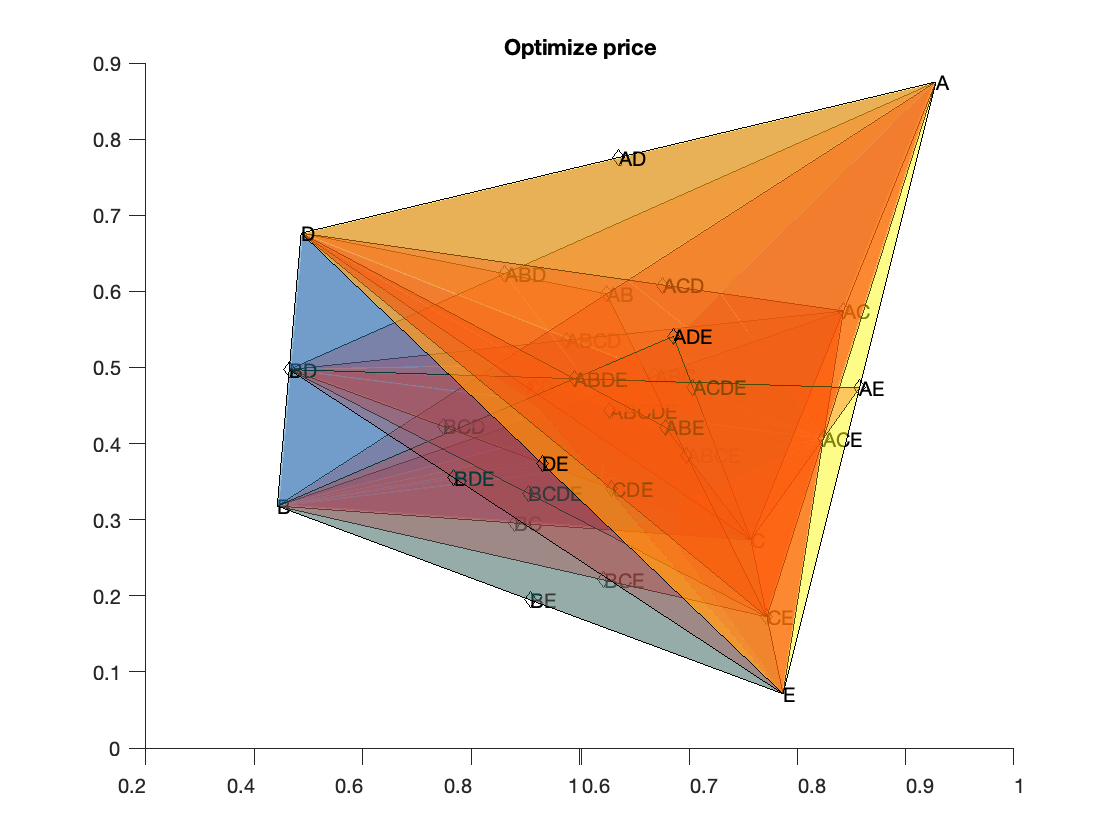

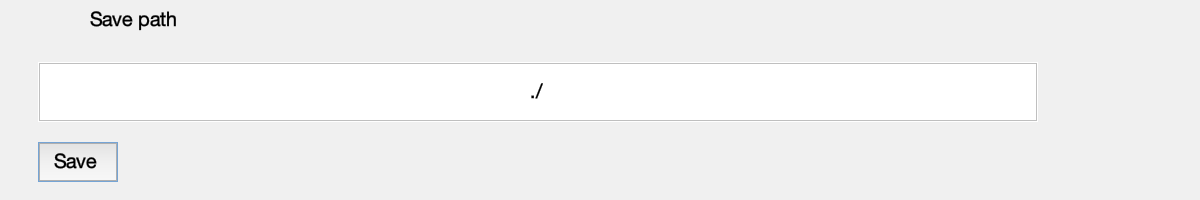

fig_sortie=figure;
set(fig_sortie, 'Position', get(fig_sortie,'Position').*[1 1 0 0] + [0 0 600 100]);
uicontrol ( fig_sortie , 'style' , ' text' , 'position', [20 70 100 30] , 'string' , 'Save path ' );
save=uicontrol ( fig_sortie , 'style' , ' edit' , 'position', [20 40 500 30] , 'string' , './' )  ;
button_save=uicontrol ( fig_sortie , 'style' , ' push' , 'position', [20 10 40 20] , 'string' , 'Save ' , 'callback','uiresume(fig_sortie)');
uiwait(fig_sortie);

### Save result 

path=get(save,'String');

parameters_file()


#### If price and number of experiments were optimized

Save targets list

if get(optimize_price_box,'Value')==1
    writematrix(["List of targets";exp_opt.list_target],path+subfolder+"/Target_list_optimize_nb_experiments.csv");
    writematrix(["List of targets";exp_opt.list_target],path+subfolder+"/Target_list_optimize_price_experiments.csv");
    writematrix(["List of possible targets","Price";prices_list],path+subfolder+"/Target price list.csv");

Save the representation of composition space and set of gradients/planes 

    
    savefig(fig_representation_exp,path+subfolder+"/Representation_experiments_optimize_nb_experiments.fig");
    savefig(fig_representation_price,path+subfolder+"/Representation_experiments_optimize_price_experiments.fig");
    if nb_cath==2
        writematrix(["Target 1","gradient center","Target 2"; price_opt.name_alignement_opt(2:end,:)], path+subfolder+"/Experimental_gradients_optimize_price_experiments.csv");
        writematrix(["Target 1","gradient center","Target 2";exp_opt.name_alignement_opt(2:end,:)], path+subfolder+"/Experimental_gradients_optimize_nb_experiments.csv");
    end
    
    if nb_cath==3
        writematrix(["Target 1","gradient center","Target 2","gradient center","Target 3","gradient center","plane center";price_opt.name_plane_opt(2:end,:)], path+subfolder+"/Experimental_plane_optimize_price_experiments.csv");
        writematrix(exp_opt.name_plane_opt(2:end,:), path+subfolder+"/Experimental_plane_optimize_nb_experiments.csv");
    end

#### If price and number of experiments were not optimized 

else
    writematrix(["List of targets";list_target(2:end,:)],path+subfolder+"/Target_list.csv");
    savefig(fig_representation,path+subfolder+"/Representation_experiments.fig");
    if nb_cath==2
        writematrix(["Target 1","gradient center","Target 2";name_alignement_opt(2:end,:)], path+subfolder+"/Experimental_gradients.csv");
    end
    
    if nb_cath==3
        writematrix(["Target 1","gradient center","Target 2","gradient center","Target 3","gradient center","plane center";name_plane_opt(2:end,:)], path+subfolder+"/Experimental_plane.csv");
    end
end


#### Display message to user

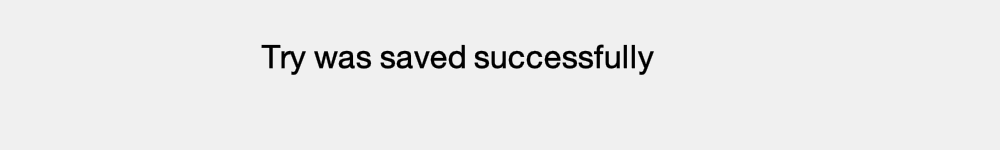

fig_success=figure;
set( fig_success ,  'position' , get(fig_success,'Position').*[1 1 0 0] + [0 -50 500 75]);
    uicontrol ( fig_success , 'style' , ' text' , 'position', [30 30 400 30] , 'FontSize', 16,'string' , 'Try was saved successfully' );